# BPSK transmission over AWGN channel

close all;clear all;clc;           % BPSK
dist=200:50:700;        % distance in meters
PtdBm=4;                % transmit power in dBm
PndBm=-85;              % noise power in dBm
Pt=10^(PtdBm/10)/1000;  % transmit power in watt
Pn=10^(PndBm/10)/1000;  % noise power in watt
Bit_Length=1e2;         % number of bits transmitted

## Friss Path Loss Model

Gt=1;
Gr=1;
freq=2.4e9;
c=3e8;
% TODO: Calculate Pr(d)
Pr=ones(length(dist),1);    % TODO: replace this with Friis' model
for d=1:length(dist)
    Pr(d)=Gt*Gr*((c/(4*pi*freq*dist(d)))^2)*Pt;
end

## BPSK Transmission over AWGN channel

tx_data = randi(2, 1, Bit_Length) - 1;                  % random between 0 and 1
x=(tx_data.*2-1)+0i;                                    % transmitted BPSK samples
n=(randn(1,Bit_Length)+randn(1,Bit_Length)*1i)/sqrt(2);  % AWGN noises
n=n*sqrt(Pn);

for d=1:length(dist)
    y(d,:)=sqrt(Pr(d))*x+n;
end

## Equalization

Detection Scheme:(Soft Detection) +1 if o/p >=0 -1 if o/p<0 Error if input and output are of different signs

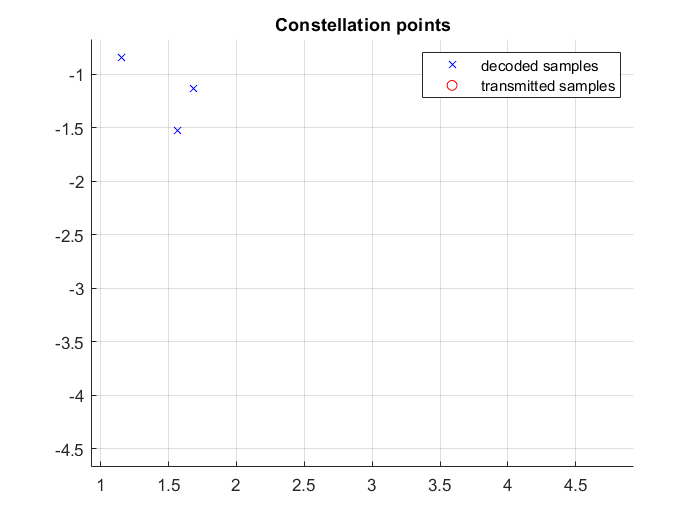

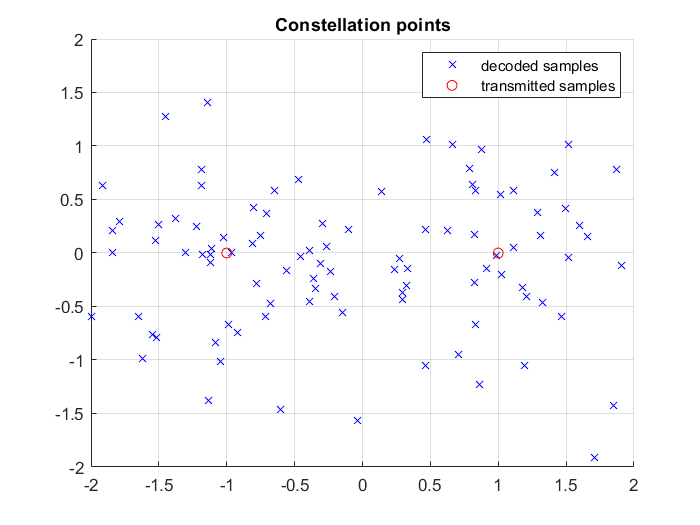

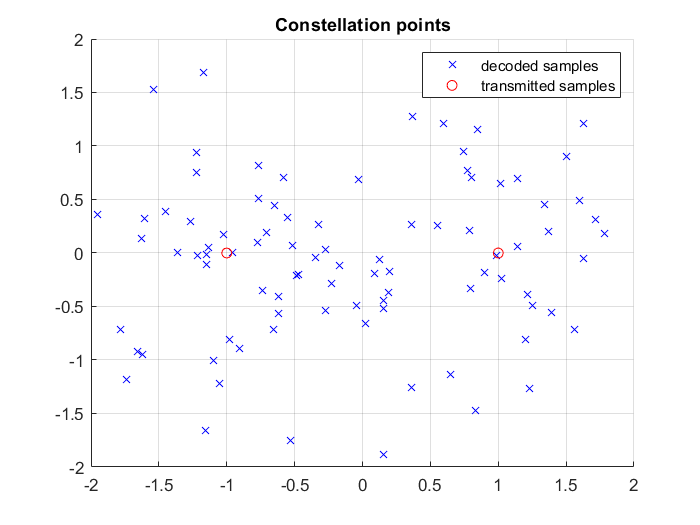

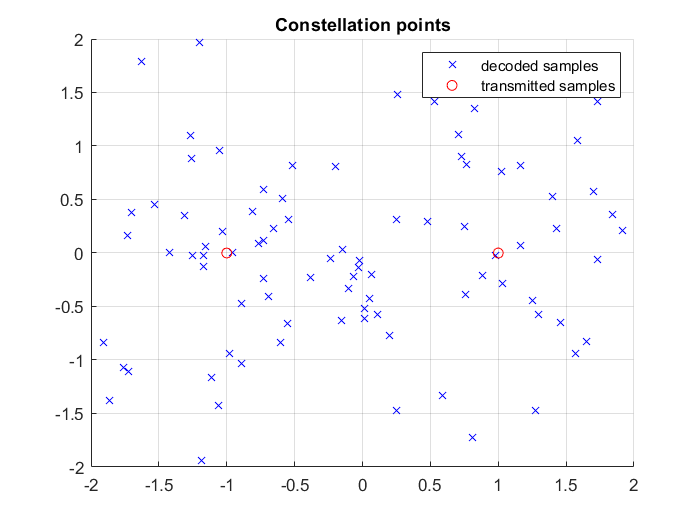

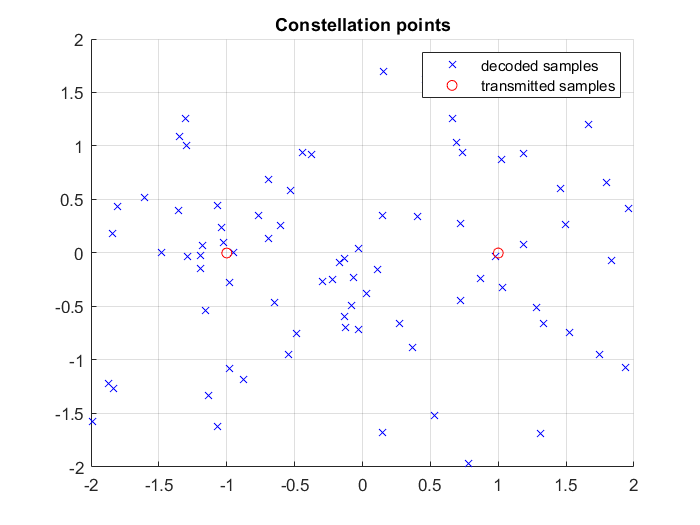

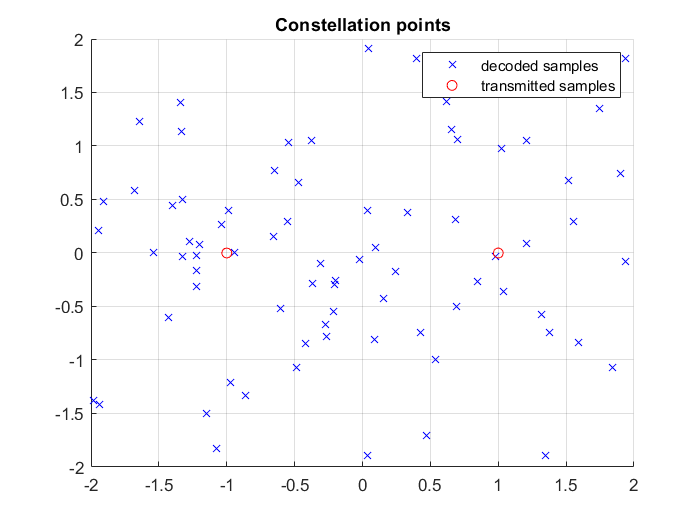

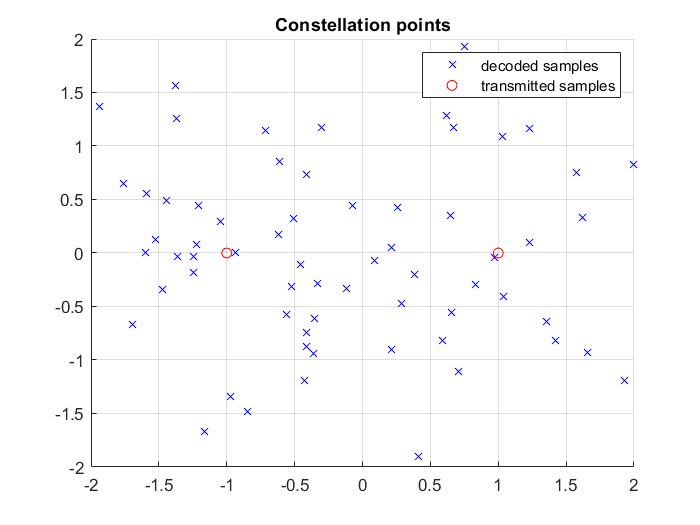

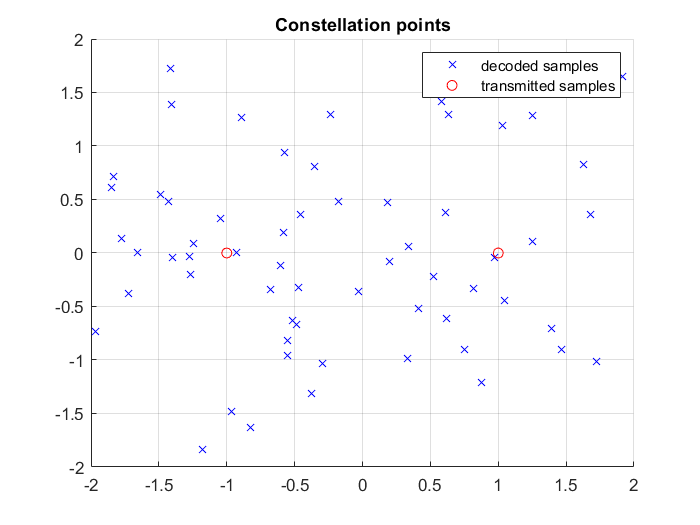

for d=1:length(dist)
    % TODO: s = y/Pr
    s=y(d,:)/sqrt(Pr(d)); % h^2=Pr
    
    % TODO: x_est = 1 if real(s) >= 0; otherwise, x_est = -1
    
    SNR(d)=Pr(d)/Pn;
    SNRdB(d)=10*log10(SNR(d));
    BER_simulated(d)=0;
    SNRdB_simulated(d)=0;
    % TODO: compare x_est with x (true value) and calculate BER_simulated(d)
    % TODO: noise = s - x, and, then, calculate SNR_simulated(d)
    
    sum_N=0;
    bit_e=0;
    
    for i=1:Bit_Length
        if real(s(i))*x(i)<0
            bit_e=bit_e+1;
        end
        n=s(i)-x(i);
        N=real(n)^2+imag(n)^2; %N=n^2
        sum_N=sum_N+N;
    end
    SNR_simulated(d)=100/sum_N;
    SNRdB_simulated(d)=10*log10(SNR_simulated(d));
    BER_simulated(d)=bit_e/Bit_Length;
    
    figure;
    hold on
    plot(s,'bx');       % TODO: replace y with s
    plot(x,0i,'ro');
    hold off
    xlim([-2,2]);
    ylim([-2,2]);
    title('Constellation points');
    legend('decoded samples', 'transmitted samples');
    grid
end

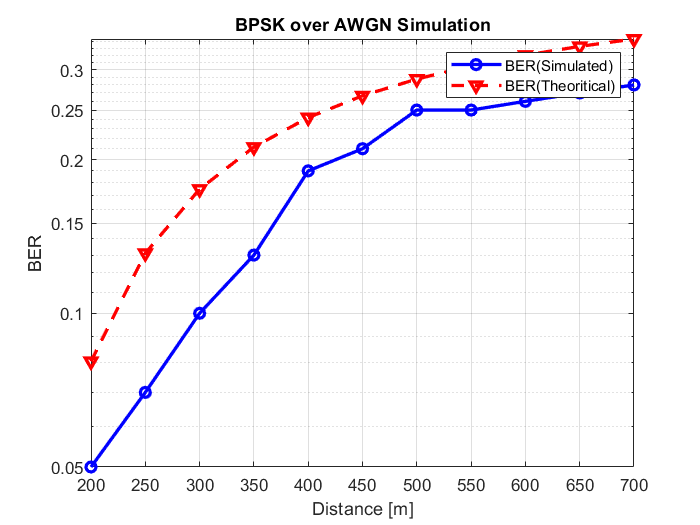



figure;
semilogy(dist,BER_simulated,'b-o','linewidth',2.0);
hold on
semilogy(dist,qfunc(sqrt(SNR)),'r--v','linewidth',2.0);
hold off
title('BPSK over AWGN Simulation');
xlabel('Distance [m]');
ylabel('BER');
legend('BER(Simulated)','BER(Theoritical)');
axis tight 
grid

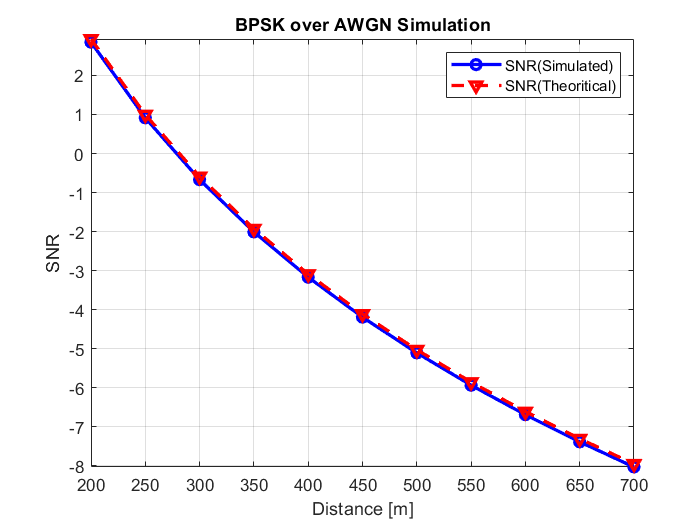


figure;
plot(dist,SNRdB_simulated,'b-o','linewidth',2.0);
hold on
plot(dist,SNRdB,'r--v','linewidth',2.0);
hold off
title('BPSK over AWGN Simulation');
xlabel('Distance [m]');
ylabel('SNR');
legend('SNR(Simulated)','SNR(Theoritical)');
axis tight 
grid